clc;
clear;
% 设置参数
fc = 17e+7;              
Nc = 128*64;  
c = 3e8; 
rangeRes = 5; 
B  = c/(2*rangeRes);               
maxR = 1000;              
tau_max = 2*maxR/c;
Tchirp = 5.5*tau_max;    
S  = B/Tchirp; 
Ns = ceil(6*(fc+B)*Tchirp);
Fs = Ns/Tchirp;
f_IFmax = S * tau_max;


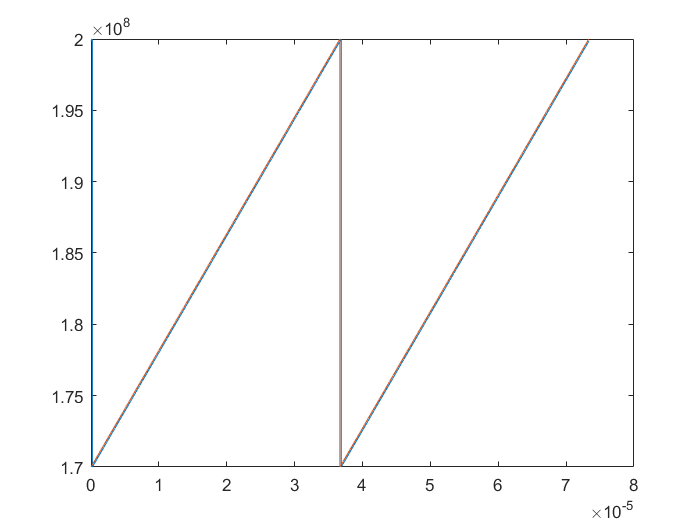

%动态目标生成
R_init = 30; 
v = 50;
n = 0:Ns*Nc-1;
t = n.*(Tchirp/Ns);

tau = 2*(R_init+v*t)./(c+v) ;

Rx = cos(2*pi*fc.*(t-tau) + S*pi.*mod((t-tau), Tchirp).^2);
Frx = fc+mod((t-tau),Tchirp).*S;

%混频的发射信号
Tx = cos(2*pi*fc.*(t)+pi*S.*mod(t, Tchirp).^2);
Fx = fc+mod(t,Tchirp).*S;

plot(t(1:2*Ns),Frx(1:2*Ns));
hold on
plot(t(1:2*Ns),Fx(1:2*Ns));
hold off

混频部分

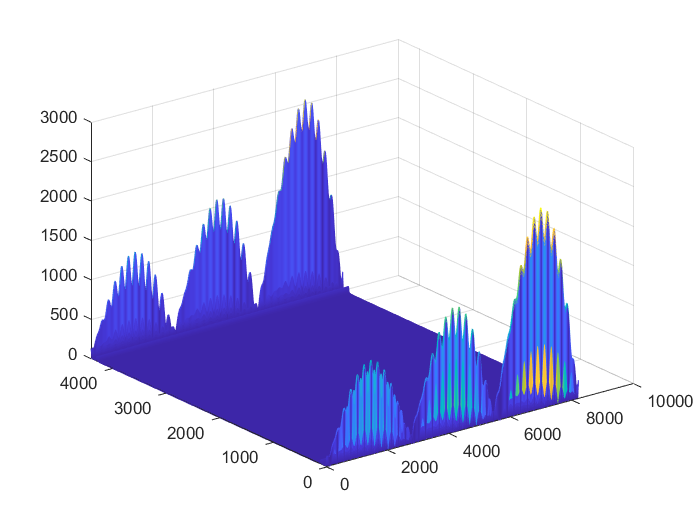

Mix = Tx.*Rx;
Mix = lowpass(Mix,1.5*f_IFmax, 4*fc);
Mix = reshape(Mix, Ns, Nc); %当加入多普勒效应时，中频信号为调频信号，reshape后每个chirp之间的相位差由相移和频移同时构成，无法解算速度？
clear Frx R_receive tau Fx Tx Rx Mix_dft
Mix_dft = abs(fft(Mix));

mesh(Mix_dft(1:10:end, :));

测距部分

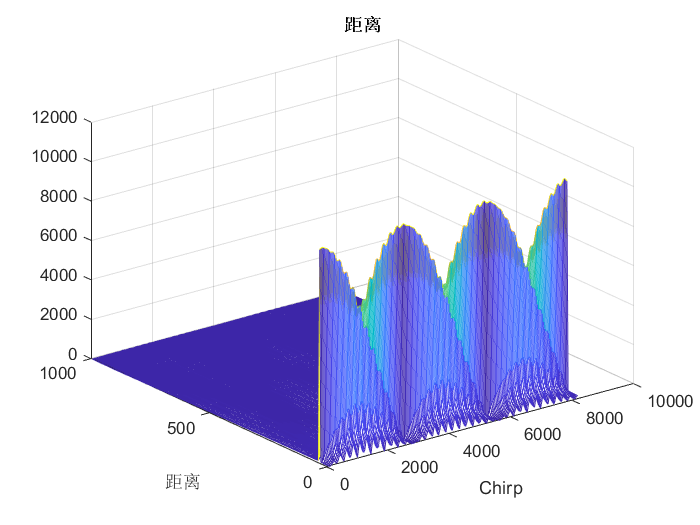


%变采样数据为二维做fft得到二维距离图像
n = 0:Ns*Nc-1;
range_axis = rangeRes * n(1:ceil(maxR/rangeRes));
sig = Mix;
sig_fft = abs(fft(sig));

sig_fft = sig_fft(1:ceil(maxR/rangeRes),: );

mesh((1:40:Nc),range_axis,sig_fft(:,(1:40:Nc)));
uicontrol('Visible','off')
xlabel('Chirp');
ylabel('距离');
title('距离');


clear sig sig_fft

速度维度的解算

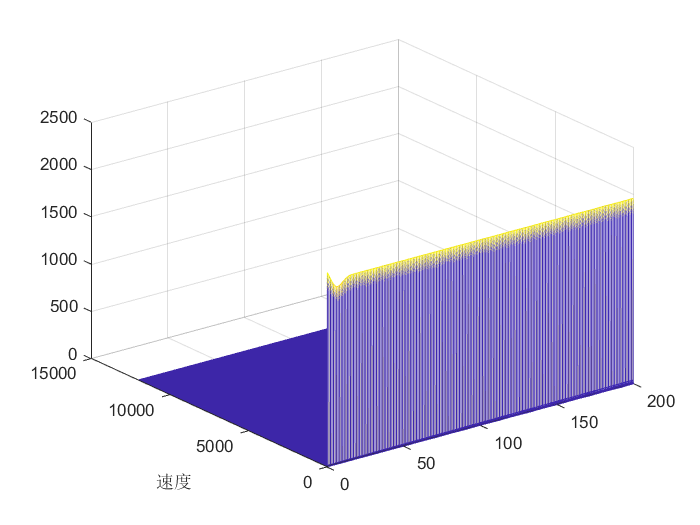


vres=(c/fc)/(2*Nc*Tchirp);
v_axis = vres * n(1:Nc/2); %正速度
sig2 = Mix';
sig2_fft = abs(fft(sig2));
sig2_fft = sig2_fft(1:Nc/2,:);

mesh((1:ceil(maxR/rangeRes)),v_axis,sig2_fft(:,1:ceil(maxR/rangeRes)));
ylabel('速度');


clear sig2 sig2_fft n t

二维fft,速度与距离的解算

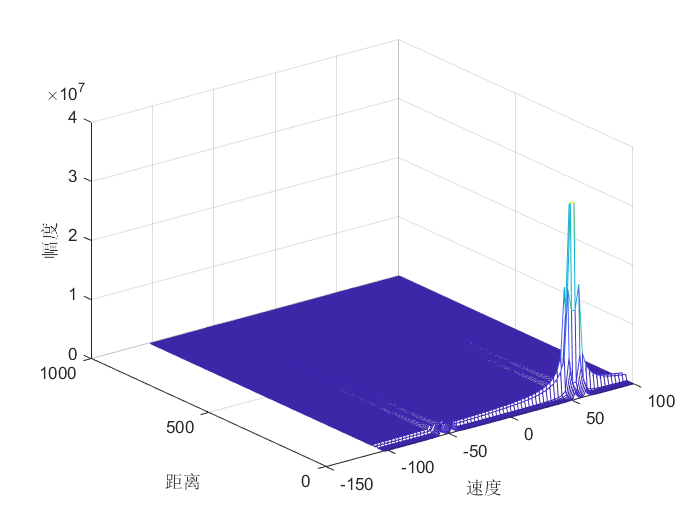



sig_fft3 = abs(fft2(Mix));
sig_fft3 = fftshift (sig_fft3);

ns  = linspace(-Ns/2,Ns/2-1,Ns); %fft以及fftshift之后，点的标位和偏移问题
range_axis = ns*rangeRes;
%nc = linspace(-Nc/2,Nc/2-1,Nc);
nc = linspace(-ceil(100/vres), ceil(100/vres)-1, 2*ceil(100/vres));
v_axis = nc*vres;
mesh(v_axis,range_axis(Ns/2:Ns/2+ceil(maxR/rangeRes)),sig_fft3(Ns/2:Ns/2+ceil(maxR/rangeRes),(Nc/2-ceil(100/vres):Nc/2+ceil(100/vres)-1)));
xlabel('速度'); ylabel('距离'); zlabel('幅度');